为什么不直接解方程呢

clear
syms p_C p_A p_3 p_4 p_5 x y F_EM 
syms m_x m_y
syms s
syms A_A A_C A_3 A_4 A_5
syms V_c V_a V_3 V_4 V_5
syms beta_e K_c K_q K_cy K_qy
syms R_1 R_2 R_3 R_4 R_L

eq1 = m_x*s^2*x == A_A*p_A - A_C*p_C

$$eq1 = m_{x}\,s^{2}\,x=A_{A}\,p_{A}-A_{C}\,p_{C}$$

eq2 = (V_c/beta_e*s+1/R_1+1/R_2)*p_C - p_A/R_1- p_3/R_2 == A_C*s*x

$$eq2 = p_{C}\,\left(\frac{1}{R_{1}}+\frac{1}{R_{2}}+\frac{V_{c}\,s}{\beta_{e}}\right)-\frac{p_{3}}{R_{2}}-\frac{p_{A}}{R_{1}}=A_{C}\,s\,x$$

eq3 = (V_a/beta_e*s+1/R_1+1/R_L + K_c)*p_A == p_C/R_1-(K_q+A_A*s)*x

$$eq3 = p_{A}\,\left(K_{c}+\frac{1}{R_{1}}+\frac{1}{R_{L}}+\frac{V_{a}\,s}{\beta_{e}}\right)=\frac{p_{C}}{R_{1}}-x\,\left(K_{q}+A_{A}\,s\right)$$

eq4 = F_EM +A_5*p_5-A_3*p_3-A_4*p_4 == -m_y*s^2*y

$$eq4 = F_{\mathrm{EM}}-A_{3}\,p_{3}-A_{4}\,p_{4}+A_{5}\,p_{5}=-m_{y}\,s^{2}\,y$$

eq5 = (V_4/beta_e*s+1/R_3+1/R_4)*p_4-1/R_4*p_5+A_4*s*y == p_3*R_3

$$eq5 = p_{4}\,\left(\frac{1}{R_{3}}+\frac{1}{R_{4}}+\frac{V_{4}\,s}{\beta_{e}}\right)-\frac{p_{5}}{R_{4}}+A_{4}\,s\,y=R_{3}\,p_{3}$$

eq6 = (V_3/beta_e*s+1/R_2+K_cy+1/R_3)*p_3 == p_C/R_2-(K_qy+A_3*s)*y+p_4/R_3

$$eq6 = p_{3}\,\left(K_{\mathrm{cy}}+\frac{1}{R_{2}}+\frac{1}{R_{3}}+\frac{V_{3}\,s}{\beta_{e}}\right)=\frac{p_{4}}{R_{3}}+\frac{p_{C}}{R_{2}}-y\,\left(K_{\mathrm{qy}}+A_{3}\,s\right)$$

eq7 = (V_5/beta_e*s+1/R_4)*p_5 == p_4/R_4+A_5*s*y

$$eq7 = p_{5}\,\left(\frac{1}{R_{4}}+\frac{V_{5}\,s}{\beta_{e}}\right)=\frac{p_{4}}{R_{4}}+A_{5}\,s\,y$$

sol1 = solve([eq1,eq2,eq3,eq4,eq5,eq6,eq7],[p_C,p_A,p_3,p_4,p_5,x,y])

sol1 = struct with fields:
    p_C: [1×1 sym]
    p_A: [1×1 sym]
    p_3: [1×1 sym]
    p_4: [1×1 sym]
    p_5: [1×1 sym]
      x: [1×1 sym]
      y: [1×1 sym]


% collect(sol1.p_C,s)

collect(sol1.p_A,s)

% [num,den] = numden(collect(sol1.p_A,s))

% [c1,t1] = coeffs(den,s)

$$t1 = \left(\begin{array}{cccccccccc} s^{9} & s^{8} & s^{7} & s^{6} & s^{5} & s^{4} & s^{3} & s^{2} & s & 1 \end{array}\right)$$

% roots(c1) 这个求根没法看
% collect(sol1.x,s)

clear
m_x = 0.06; 
m_y = 8e-4;
A_A = 1.7e-4;
A_C = 2e-4;
V_c = 1e-6;
V_a = 2e-3;
beta_e = 7e8;
K_c = 5e-10;
K_q = 3.3;
R_1 = 3e10;
R_2 = 2e11;
R_L = R_2;
p_3 = 1;
s = tf('s');

sys1 = (R_L*m_x*p_3*beta_e^2*s^2 + A_A*A_C*R_1*R_L*p_3*beta_e^2*s + A_C*K_q*R_1*R_L*p_3*beta_e^2)/(R_1*R_2*R_L*V_a*V_c*m_x*s^4 + (R_1*R_2*V_c*beta_e*m_x + R_1*R_L*V_a*beta_e*m_x + R_2*R_L*V_a*beta_e*m_x + R_2*R_L*V_c*beta_e*m_x + K_c*R_1*R_2*R_L*V_c*beta_e*m_x)*s^3 + (R_1*beta_e^2*m_x + R_2*beta_e^2*m_x + R_L*beta_e^2*m_x + K_c*R_1*R_L*beta_e^2*m_x + K_c*R_2*R_L*beta_e^2*m_x + A_A^2*R_1*R_2*R_L*V_c*beta_e + A_C^2*R_1*R_2*R_L*V_a*beta_e)*s^2 + (A_C^2*R_1*R_2*beta_e^2 + A_A^2*R_1*R_L*beta_e^2 + A_A^2*R_2*R_L*beta_e^2 + A_C^2*R_2*R_L*beta_e^2 - 2*A_A*A_C*R_2*R_L*beta_e^2 + A_C^2*K_c*R_1*R_2*R_L*beta_e^2 + A_A*K_q*R_1*R_2*R_L*V_c*beta_e)*s + A_A*K_q*R_1*R_L*beta_e^2 + A_A*K_q*R_2*R_L*beta_e^2 - A_C*K_q*R_2*R_L*beta_e^2)


sys1 =
 
                                                
              5.88e27 s^2 + 9.996e31 s + 1.94e36
                                                
  ----------------------------------------------------------
                                                            
  1.44e23 s^4 + 3.891e27 s^3 + 6.791e31 s^2 + 1.245e34 s    
                                                            
                                                  - 2.911e35
                                                            
 
Continuous-time transfer function.



syszpk = zpk(sys1)


syszpk =
 
           40833 (s^2 + 1.7e04s + 3.3e08)
  ------------------------------------------------
  (s+206.5) (s-20.97) (s^2 + 2.684e04s + 4.666e08)
 
Continuous-time zero/pole/gain model.



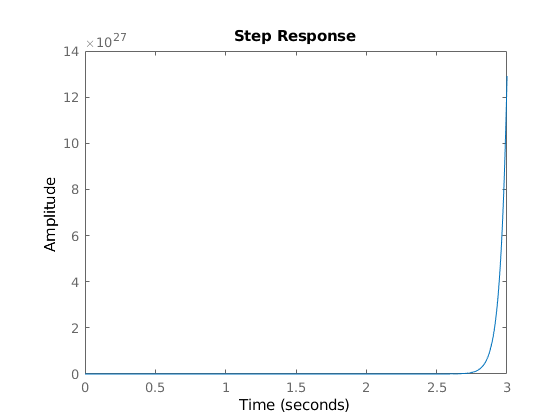


step(sys1);